1. Implementati formula repetata a trapezului, dreptunghiului si a lui Simpson.

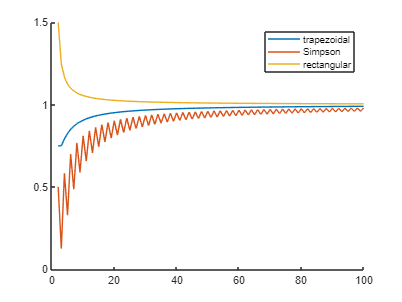

T = []; S=[]; R=[];
X = 2:100;
for x=X
    [t,s,r]=get_area(x);
    T=[T,t]; S=[S,s]; R=[R,r];
end

clf; hold on;
plot(X, T);
plot(X, S);
plot(X, R);
legend("trapezoidal", "Simpson", "rectangular")
hold off;


[t,s,r] = get_area(100)

t = 0.9901

s = 0.9801

r = 1.0051

function [t, s, r] = get_area(len)
    a = 0; b = 1;    
    x = linspace(a, b, int32(len));    
    y = 3*x.*x;
    
    t = trapezoidal(a,b,y);
    s = simpson(a,b,y);
    r = rectangular(a,b,y);
end

function A = trapezoidal(a, b, y)
    n = size(y,2);
    A = ((b-a)/(2*n))*(y(1)+y(n)+2*sum(y(2:n-1)));
end

function A = simpson(a, b, y)
    n = size(y,2); 
    m = floor(n/2);
    A = ((b-a)/(6*m))*(y(1)+y(2*m) + 2*sum(y(3:2:(2*m-1))) + 4*sum(y(2:2:(2*m-2))));
end

function A = rectangular(a, b, y)
    n = size(y,2);
    A = (b-a)/n*sum(y);
end